clear
load('airfoilDB.mat')
load('structure_controlpacket.mat')
[T, a.cruise, P, rho.cruise] = atmosisa(25000*0.3048);
[T, a.sealevel, P, rho.sealevel] = atmosisa(0);
clear T P



## Graphing

% Customize default settings
set(0, 'DefaultAxesFontSize', 15);              % Increase default font size of axes
set(0, 'DefaultAxesLineWidth', 2);            % Increase default line width of axes
set(groot, 'DefaultLineLineWidth', 2);               % Increase default line thickness

set(0, 'DefaultAxesTickLength', [0.04 0.04]);
set(0, 'DefaultLineMarkerSize', 12); % Increase default tick length of axes
% set(0, 'DefaultAxesTitleFontSize', 16);         % Increase default title font size

## Conditions for cruise

Condition.WS = 3332;
Condition.discret = 0.01;
Condition.Cruise_Mach = 0.45;
Condition.Uinf = Condition.Cruise_Mach*a.cruise;
Condition.Prandtlglauert = sqrt(1-Condition.Cruise_Mach);
Condition.MTOW = 29748 * 9.81;

## Aircraft basic properties

Aircraft.Sref = Condition.MTOW/Condition.WS;
Aircraft.AR = 10;
Aircraft.Sweep = 0;
Aircraft.Taper = 0.79;
Aircraft.fuselage_rad = 1.15;
Aircraft.V_stall_sealevel = sqrt(Condition.WS*2/(rho.sealevel*2.7));

## Basic wing parameters

Wing.twist = -3*pi/180;
Wing.panelnum = 20;
Wing.incidence = 0*pi/180;
% 4.5*pi/180;

## Tip and root airfoils (center line)

Airfoil(1).Field = 'root';
Airfoil(1).alpha0 = airfoilDB(62).reDB(3).aoa0*pi/180;
% airfoil(1).alpha0 = 0;
Airfoil(1).a = airfoilDB(62).reDB(3).liftCurve;
% airfoil(1).a = 2*pi;
Airfoil(2).Field = 'tip';
Airfoil(2).alpha0 = airfoilDB(62).reDB(3).aoa0*pi/180;
% airfoil(2).alpha0 = 0;
Airfoil(2).a = airfoilDB(62).reDB(3).liftCurve;
% airfoil(2).a = 2*pi;
Airfoil(1).stallaoa = airfoilDB(62).reDB(3).aoa0*pi/180;
Airfoil(2).stallaoa = airfoilDB(62).reDB(3).aoa0*pi/180;
Airfoil(1).aoacl = airfoilDB(62).reDB(3).aoaCl*pi/180;
Airfoil(2).aoacl = airfoilDB(62).reDB(3).aoaCl*pi/180;
Airfoil(1).cl = airfoilDB(62).reDB(3).cl;
Airfoil(2).cl = airfoilDB(62).reDB(3).cl;
Airfoil(1).cm = airfoilDB(62).reDB(3).cm;
Airfoil(2).cm = airfoilDB(62).reDB(3).cm;
Airfoil(1).aoacm = airfoilDB(62).reDB(3).aoaCm*pi/180;
Airfoil(2).aoacm = airfoilDB(62).reDB(3).aoaCm*pi/180;
% plot(Airfoil(2).aoacl,Airfoil(2).cl);

## Discritize planform to plot

[Wing.c_y, Wing.span_disc,Wing.quarterchord,Wing.c_bar,Wing.span] = planformcalc(Aircraft.AR, Aircraft.Sweep, Aircraft.Taper, Aircraft.Sref, Condition.discret);

Wing.S_rat = trapz(Wing.span_disc(find(Wing.span_disc >= Aircraft.fuselage_rad)),Wing.c_y(find(Wing.span_disc >= Aircraft.fuselage_rad)))/trapz(Wing.span_disc,Wing.c_y);
Aircraft.FLF = 1.07*(1+ Aircraft.fuselage_rad*2/Wing.span)^2;

## Adding fuselage effects

% Aircraft.Oswald = 1/1.15;
% CL_reduced_fuselage = sqrt(Wing.CD_des_ind*pi*Aircraft.AR*Aircraft.Oswald );
% Wing.CL_des_delta = Wing.CL_des - CL_reduced_fuselage;
% Wing.CD_des_delta = Wing.CL_des_delta.^2/(pi*Aircraft.AR*Aircraft.Oswald);
% Wing.Liftloss = Wing.CL_des_delta.*0.5*rho.cruise*Condition.Uinf.^2*Aircraft.Sref;
% Wing.dragloss = Wing.CD_des_delta.*0.5*rho.cruise*Condition.Uinf.^2*Aircraft.Sref;
% 
% Wing.Lift_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) = Wing.Lift_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) - Wing.Liftloss / (2*Aircraft.fuselage_rad);
% Wing.Lift_ellipse_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) = Wing.Lift_ellipse_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) - Wing.Liftloss / (2*Aircraft.fuselage_rad);
% 
% Wing.DragI_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) = Wing.DragI_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) - Wing.dragloss / (2*Aircraft.fuselage_rad);
% Wing.DragI_elliptical_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) = Wing.DragI_elliptical_plot(find(Wing.span_disc <= Aircraft.fuselage_rad)) - Wing.dragloss / (2*Aircraft.fuselage_rad);
% 


## Plotting

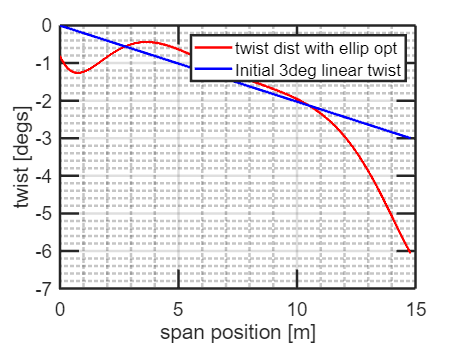

Wing.semispan = Wing.span*0.5;
Wing.thetadist = acos(Wing.span_disc/Wing.span_disc(end));

Angle.twist_dis = linspace(0,Wing.twist,length(Wing.span_disc));
Angle.defaulttwist = Angle.twist_dis;
Angle.twist_dis = Structure_packet.twist_plot*pi/180;

Angle.alpha_0_dis = linspace(Airfoil(1).alpha0,Airfoil(2).alpha0,length(Wing.span_disc));
Angle.incidence_dis = Wing.incidence*ones(1,length(Wing.span_disc));
Angle.alpha_dis = Angle.twist_dis - Angle.alpha_0_dis + Angle.incidence_dis;

Wing.a_dis = linspace(Airfoil(1).a,Airfoil(2).a,length(Wing.span_disc));
Wing.mu_dis = (Wing.a_dis.*Wing.c_y)/(4.*Aircraft.AR*Wing.c_bar);


[Wing.Lift_plot,Wing.Lift_ellipse_plot,Wing.DragI_plot,Aircraft.Totallift,Aircraft.Totalliftcheck_nofuselage,Wing.Cl_plot,Wing.Cl_ellipse_plot,Wing.CDi_plot, Wing.CL_des,Wing.CD_des_ind,Wing.Aseries,Wing.DragI_elliptical_plot,Wing.CDi_elliptical_plot] = Plotting(Angle.twist_dis, Angle.alpha_0_dis, Angle.incidence_dis, Wing.thetadist, Wing.panelnum, Wing.mu_dis,Wing.semispan,Condition.Uinf,rho.cruise,Wing.c_y,Aircraft.Sref,Condition.Cruise_Mach,Aircraft.AR,Condition.MTOW,Aircraft.fuselage_rad,Wing.span_disc);

% Wing.Cl_noliftline = Angle.alpha_dis .* Airfoil(1).a



plot(Wing.span_disc,Angle.twist_dis*180/pi ,'r')
hold on
plot(Wing.span_disc,Angle.defaulttwist*180/pi ,'b')
hold off
% + Angle.incidence_dis*180/pi
grid on
grid minor
xlabel('span position [m]')
ylabel('twist [degs]')
legend('twist dist with ellip opt','Initial 3deg linear twist')




disp('Liftproduced')

Liftproduced


disp(Aircraft.Totallift)

   8.4973e+04



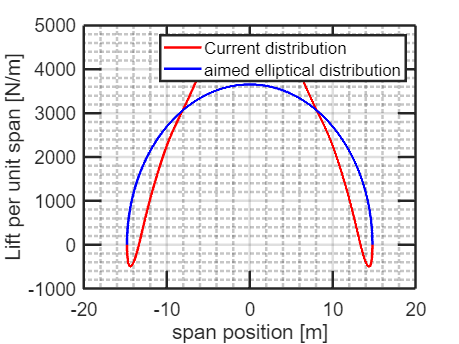



plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot,'r')

plot(-Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')
plot(Wing.semispan*cos(Wing.thetadist),Wing.Lift_ellipse_plot,'b')

% 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot)

grid on
grid minor
xlabel('span position [m]')
ylabel('Lift per unit span [N/m]')
legend('Current distribution','','aimed elliptical distribution')

hold off

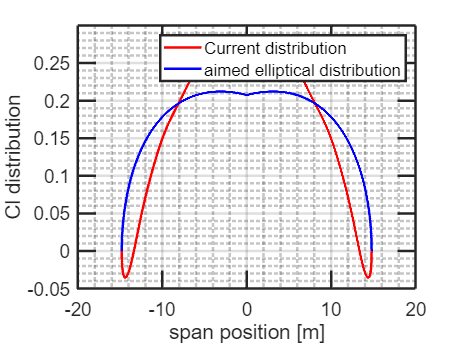



plot(Wing.semispan*cos(Wing.thetadist),Wing.Cl_plot,'r')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.Cl_plot,'r')

% plot(Wing.semispan*cos(Wing.thetadist),Wing.Cl_noliftline,'g')
% hold on
% plot(-Wing.semispan*cos(Wing.thetadist),Wing.Cl_noliftline,'g')


plot(-Wing.semispan*cos(Wing.thetadist),Wing.Cl_ellipse_plot,'b')
plot(Wing.semispan*cos(Wing.thetadist),Wing.Cl_ellipse_plot,'b')

% 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot)

grid on
grid minor
xlabel('span position [m]')
ylabel('Cl distribution')
legend('Current distribution','','aimed elliptical distribution')

hold off

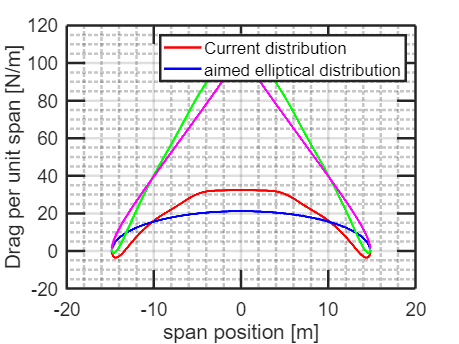


Wing.CD0_dist = [0.00472765614257932	0.00472452004329520	0.00472138394401108	0.00471824784472696	0.00471511174544284	0.00471197564615872	0.00470883954687461	0.00470570344759049	0.00470256734830637	0.00469943124902225	0.00469629514973813	0.00469315905045401	0.00469002295116989	0.00468688685188577	0.00468375075260165	0.00468061465331753	0.00467747855403341	0.00467434245474929	0.00467120635546517	0.00466807025618105	0.00466493415689693	0.00466179805761282	0.00465866195832870	0.00465552585904458	0.00465238975976046	0.00464925366047634	0.00464611756119222	0.00464298146190810	0.00463984536262398	0.00463670926333986	0.00463357316405574	0.00463043706477162	0.00462730096548750	0.00462416486620338	0.00462102876691926	0.00461789266763514	0.00461475656835102	0.00461162046906691	0.00460848436978279	0.00460534827049867	0.00460221217121455	0.00459907607193043	0.00459593997264631	0.00459280387336219	0.00458966777407807	0.00458653167479395	0.00458339557550983	0.00458025947622571	0.00457712337694159	0.00457398727765747	0.00457085117837335	0.00456771507908923	0.00456457897980511	0.00456144288052100	0.00455830678123688	0.00455517068195276	0.00455203458266864	0.00454889848338452	0.00454576238410040	0.00454262628481628	0.00453949018553216	0.00453635408624804	0.00453321798696392	0.00453008188767980	0.00452694578839568	0.00452380968911156	0.00452067358982744	0.00451753749054333	0.00451440139125921	0.00451126529197509	0.00450812919269097	0.00450499309340685	0.00450185699412273	0.00449872089483861	0.00449558479555449	0.00449244869627037	0.00448931259698625	0.00448617649770213	0.00448304039841801	0.00447990429913389	0.00447676819984977	0.00447363210056565	0.00447049600128153	0.00446735990199742	0.00446422380271330	0.00446108770342918	0.00445795160414506	0.00445481550486094	0.00445167940557682	0.00444854330629270	0.00444540720700858	0.00444227110772446	0.00443913500844034	0.00443599890915622	0.00443286280987210	0.00442972671058798	0.00442659061130386	0.00442345451201974	0.00442031841273562	0.00441718231345151	0.00441404621416739	0.00441091011488327	0.00440777401559915	0.00440463791631503	0.00440150181703091	0.00439836571774679	0.00439522961846267	0.00439209351917855	0.00438895741989443	0.00438582132061031	0.00438268522132619	0.00437954912204207	0.00437641302275795	0.00437327692347383	0.00437014082418971	0.00436700472490560	0.00436386862562148	0.00436073252633736	0.00435759642705324	0.00435446032776912	0.00435132422848500	0.00434818812920088	0.00434505202991676	0.00434191593063264	0.00433877983134852	0.00433564373206440	0.00433250763278028	0.00432937153349616	0.00432623543421204	0.00432309933492792	0.00431996323564380	0.00431682713635969	0.00431369103707557	0.00431055493779145	0.00430741883850733	0.00430428273922321	0.00430114663993909	0.00429801054065497	0.00429487444137085	0.00429173834208673	0.00428860224280261	0.00428546614351849	0.00428233004423437	0.00427919394495025	0.00427605784566613	0.00427292174638202	0.00426978564709790	0.00426664954781378	0.00426351344852966	0.00426037734924554	0.00425724124996142	0.00425410515067730	0.00425096905139318	0.00424783295210906	0.00424469685282494	0.00424156075354082	0.00423842465425670	0.00423528855497258	0.00423215245568846	0.00422901635640434	0.00422588025712022	0.00422274415783610	0.00421960805855199	0.00421647195926787	0.00421333585998375	0.00421019976069963	0.00420706366141551	0.00420392756213139	0.00420079146284727	0.00419765536356315	0.00419451926427903	0.00419138316499491	0.00418824706571079	0.00418511096642667	0.00418197486714255	0.00417883876785843	0.00417570266857431	0.00417256656929020	0.00416943047000608	0.00416629437072196	0.00416315827143784	0.00416002217215372	0.00415688607286960	0.00415374997358548	0.00415061387430136	0.00414747777501724	0.00414434167573312	0.00414120557644900	0.00413806947716488	0.00413493337788076	0.00413179727859664	0.00412866117931252	0.00412552508002841	0.00412238898074429	0.00411925288146017	0.00411611678217605	0.00411298068289193	0.00410984458360781	0.00410670848432369	0.00410357238503957	0.00410043628575545	0.00409730018647133	0.00409416408718721	0.00409102798790309	0.00408789188861897	0.00408475578933485	0.00408161969005073	0.00407848359076661	0.00407534749148249	0.00407221139219838	0.00406907529291426	0.00406593919363014	0.00406280309434602	0.00405966699506190	0.00405653089577778	0.00405339479649366	0.00405025869720954	0.00404712259792542	0.00404398649864130	0.00404085039935718	0.00403771430007306	0.00403457820078894	0.00403144210150482	0.00402830600222070	0.00402516990293658	0.00402203380365247	0.00401889770436835	0.00401576160508423	0.00401262550580011	0.00400948940651599	0.00400635330723187	0.00400321720794775	0.00400008110866363	0.00399694500937951	0.00399380891009539	0.00399067281081127	0.00398753671152715	0.00398440061224303	0.00398126451295891	0.00397812841367479	0.00397499231439068	0.00397185621510656	0.00396872011582244	0.00396558401653832	0.00396244791725420	0.00395931181797008	0.00395617571868596	0.00395303961940184	0.00394990352011772	0.00394676742083360	0.00394363132154948	0.00394049522226536	0.00393735912298124	0.00393422302369712	0.00393108692441300	0.00392795082512889	0.00392481472584477	0.00392167862656065	0.00391854252727653	0.00391540642799241	0.00391227032870829	0.00390913422942417	0.00390599813014005	0.00390286203085593	0.00389972593157181	0.00389658983228769	0.00389345373300357	0.00389031763371945	0.00388718153443533	0.00388404543515121	0.00388090933586709	0.00387777323658298	0.00387463713729886	0.00387150103801474	0.00386836493873062	0.00386522883944650	0.00386209274016238	0.00385895664087826	0.00385582054159414	0.00385268444231002	0.00384954834302590	0.00384641224374178	0.00384327614445766	0.00384014004517354	0.00383700394588942	0.00383386784660530	0.00383073174732118	0.00382759564803706	0.00382445954875295	0.00382132344946883	0.00381818735018471	0.00381505125090059	0.00381191515161647	0.00380877905233235	0.00380564295304823	0.00380250685376411	0.00379937075447999	0.00379623465519587	0.00379309855591175	0.00378996245662763	0.00378682635734351	0.00378369025805939	0.00378055415877527	0.00377741805949116	0.00377428196020704	0.00377114586092292	0.00376800976163880	0.00376487366235468	0.00376173756307056	0.00375860146378644	0.00375546536450232	0.00375232926521820	0.00374919316593408	0.00374605706664996	0.00374292096736584	0.00373978486808172	0.00373664876879760	0.00373351266951348	0.00373037657022936	0.00372724047094525	0.00372410437166113	0.00372096827237701	0.00371783217309289	0.00371469607380877	0.00371155997452465	0.00370842387524053	0.00370528777595641	0.00370215167667229	0.00369901557738817	0.00369587947810405	0.00369274337881993	0.00368960727953581	0.00368647118025169	0.00368333508096757	0.00368019898168346	0.00367706288239934	0.00367392678311522	0.00367079068383110	0.00366765458454698	0.00366451848526286	0.00366138238597874	0.00365824628669462	0.00365511018741050	0.00365197408812638	0.00364883798884226	0.00364570188955814	0.00364256579027402	0.00363942969098990	0.00363629359170578	0.00363315749242166	0.00363002139313755	0.00362688529385343	0.00362374919456931	0.00362061309528519	0.00361747699600107	0.00361434089671695	0.00361120479743283	0.00360806869814871	0.00360493259886459	0.00360179649958047	0.00359866040029635	0.00359552430101223	0.00359238820172811	0.00358925210244399	0.00358611600315987	0.00358297990387575	0.00357984380459164	0.00357670770530752	0.00357357160602340	0.00357043550673928	0.00356729940745516	0.00356416330817104	0.00356102720888692	0.00355789110960280	0.00355475501031868	0.00355161891103456	0.00354848281175044	0.00354534671246632	0.00354221061318220	0.00353907451389808	0.00353593841461396	0.00353280231532985	0.00352966621604573	0.00352653011676161	0.00352339401747749	0.00352025791819337	0.00351712181890925	0.00351398571962513	0.00351084962034101	0.00350771352105689	0.00350457742177277	0.00350144132248865	0.00349830522320453	0.00349516912392041	0.00349203302463629	0.00348889692535217	0.00348576082606805	0.00348262472678394	0.00347948862749982	0.00347635252821570	0.00347321642893158	0.00347008032964746	0.00346694423036334	0.00346380813107922	0.00346067203179510	0.00345753593251098	0.00345439983322686	0.00345126373394274	0.00344812763465862	0.00344499153537450	0.00344185543609039	0.00343871933680627	0.00343558323752215	0.00343244713823803	0.00342931103895391	0.00342617493966979	0.00342303884038567	0.00341990274110155	0.00341676664181743	0.00341363054253331	0.00341049444324919	0.00340735834396507	0.00340422224468095	0.00340108614539684	0.00339795004611272	0.00339481394682860	0.00339167784754448	0.00338854174826036	0.00338540564897624	0.00338226954969212	0.00337913345040800	0.00337599735112388	0.00337286125183976	0.00336972515255564	0.00336658905327152	0.00336345295398740	0.00336031685470329	0.00335718075541917	0.00335404465613505	0.00335090855685093	0.00334777245756681	0.00334463635828269	0.00334150025899857	0.00333836415971445	0.00333522806043033	0.00333209196114621	0.00332895586186209	0.00332581976257797	0.00332268366329385	0.00331954756400974	0.00331641146472562	0.00331327536544150	0.00331013926615738	0.00330700316687326	0.00330386706758914	0.00330073096830502	0.00329759486902090	0.00329445876973678	0.00329132267045266	0.00328818657116854	0.00328505047188442	0.00328191437260030	0.00327877827331619	0.00327564217403207	0.00327250607474795	0.00326936997546383	0.00326623387617971	0.00326309777689559	0.00325996167761147	0.00325682557832735	0.00325368947904323	0.00325055337975911	0.00324741728047499	0.00324428118119087	0.00324114508190675	0.00323800898262264	0.00323487288333852	0.00323173678405440	0.00322860068477028	0.00322546458548616	0.00322232848620204	0.00321919238691792	0.00321605628763380	0.00321292018834968	0.00320978408906556	0.00320664798978144	0.00320351189049732	0.00320037579121321	0.00319723969192909	0.00319410359264497	0.00319096749336085	0.00318783139407673	0.00318469529479261	0.00318155919550849	0.00317842309622437	0.00317528699694025	0.00317215089765613	0.00316901479837201	0.00316587869908789	0.00316274259980377	0.00315960650051966	0.00315647040123554	0.00315333430195142	0.00315019820266730	0.00314706210338318	0.00314392600409906	0.00314078990481494	0.00313765380553082	0.00313451770624670	0.00313138160696258	0.00312824550767846	0.00312510940839434	0.00312197330911022	0.00311883720982611	0.00311570111054199	0.00311256501125787	0.00310942891197375	0.00310629281268963	0.00310315671340551	0.00310002061412139	0.00309688451483727	0.00309374841555315	0.00309061231626903	0.00308747621698491	0.00308434011770079	0.00308120401841667	0.00307806791913256	0.00307493181984844	0.00307179572056432	0.00306865962128020	0.00306552352199608	0.00306238742271196	0.00305925132342784	0.00305611522414372	0.00305297912485960	0.00304984302557548	0.00304670692629136	0.00304357082700724	0.00304043472772312	0.00303729862843901	0.00303416252915489	0.00303102642987077	0.00302789033058665	0.00302475423130253	0.00302161813201841	0.00301848203273429	0.00301534593345017	0.00301220983416605	0.00300907373488193	0.00300593763559781	0.00300280153631369	0.00299966543702957	0.00299652933774546	0.00299339323846134	0.00299025713917722	0.00298712103989310	0.00298398494060898	0.00298084884132486	0.00297771274204074	0.00297457664275662	0.00297144054347250	0.00296830444418838	0.00296516834490426	0.00296203224562014	0.00295889614633602	0.00295576004705191	0.00295262394776779	0.00294948784848367	0.00294635174919955	0.00294321564991543	0.00294007955063131	0.00293694345134719	0.00293380735206307	0.00293067125277895	0.00292753515349483	0.00292439905421071	0.00292126295492659	0.00291812685564248	0.00291499075635836	0.00291185465707424	0.00290871855779012	0.00290558245850600	0.00290244635922188	0.00289931025993776	0.00289617416065364	0.00289303806136952	0.00288990196208540	0.00288676586280128	0.00288362976351716	0.00288049366423304	0.00287735756494892	0.00287422146566481	0.00287108536638069	0.00286794926709657	0.00286481316781245	0.00286167706852833	0.00285854096924421	0.00285540486996009	0.00285226877067597	0.00284913267139185	0.00284599657210773	0.00284286047282361	0.00283972437353949	0.00283658827425538	0.00283345217497126	0.00283031607568714	0.00282717997640302	0.00282404387711890	0.00282090777783478	0.00281777167855066	0.00281463557926654	0.00281149947998242	0.00280836338069830	0.00280522728141418	0.00280209118213006	0.00279895508284594	0.00279581898356183	0.00279268288427771	0.00278954678499359	0.00278641068570947	0.00278327458642535	0.00278013848714123	0.00277700238785711	0.00277386628857299	0.00277073018928887	0.00276759409000475	0.00276445799072063	0.00276132189143651	0.00275818579215239	0.00275504969286828	0.00275191359358416	0.00274877749430004	0.00274564139501592	0.00274250529573180	0.00273936919644768	0.00273623309716356	0.00273309699787944	0.00272996089859532	0.00272682479931120	0.00272368870002708	0.00272055260074296	0.00271741650145884	0.00271428040217473	0.00271114430289061	0.00270800820360649	0.00270487210432237	0.00270173600503825	0.00269859990575413	0.00269546380647001	0.00269232770718589	0.00268919160790177	0.00268605550861765	0.00268291940933353	0.00267978331004941	0.00267664721076530	0.00267351111148118	0.00267037501219706	0.00266723891291294	0.00266410281362882	0.00266096671434470	0.00265783061506058	0.00265469451577646	0.00265155841649234	0.00264842231720822	0.00264528621792410	0.00264215011863998	0.00263901401935586	0.00263587792007175	0.00263274182078763	0.00262960572150351	0.00262646962221939	0.00262333352293527	0.00262019742365115	0.00261706132436703	0.00261392522508291	0.00261078912579879	0.00260765302651467	0.00260451692723055	0.00260138082794643	0.00259824472866231	0.00259510862937820	0.00259197253009408	0.00258883643080996	0.00258570033152584	0.00258256423224172	0.00257942813295760	0.00257629203367348	0.00257315593438936	0.00257001983510524	0.00256688373582112	0.00256374763653700	0.00256061153725288	0.00255747543796876	0.00255433933868465	0.00255120323940053	0.00254806714011641	0.00254493104083229	0.00254179494154817	0.00253865884226405	0.00253552274297993	0.00253238664369581	0.00252925054441169	0.00252611444512757	0.00252297834584345	0.00251984224655933	0.00251670614727521	0.00251357004799109	0.00251043394870698	0.00250729784942286	0.00250416175013874	0.00250102565085462	0.00249788955157050	0.00249475345228638	0.00249161735300226	0.00248848125371814	0.00248534515443402	0.00248220905514990	0.00247907295586578	0.00247593685658166	0.00247280075729755	0.00246966465801343	0.00246652855872931	0.00246339245944519	0.00246025636016107	0.00245712026087695	0.00245398416159283	0.00245084806230871	0.00244771196302459	0.00244457586374047	0.00244143976445635	0.00243830366517223	0.00243516756588812	0.00243203146660400	0.00242889536731988	0.00242575926803576	0.00242262316875164	0.00241948706946752	0.00241635097018340	0.00241321487089928	0.00241007877161516	0.00240694267233104	0.00240380657304692	0.00240067047376280	0.00239753437447868	0.00239439827519456	0.00239126217591045	0.00238812607662633	0.00238498997734221	0.00238185387805809	0.00237871777877397	0.00237558167948985	0.00237244558020573	0.00236930948092161	0.00236617338163749	0.00236303728235337	0.00235990118306925	0.00235676508378513	0.00235362898450102	0.00235049288521690	0.00234735678593278	0.00234422068664866	0.00234108458736454	0.00233794848808042	0.00233481238879630	0.00233167628951218	0.00232854019022806	0.00232540409094394	0.00232226799165982	0.00231913189237570	0.00231599579309158	0.00231285969380747	0.00230972359452335	0.00230658749523923	0.00230345139595511	0.00230031529667099	0.00229717919738687	0.00229404309810275	0.00229090699881863	0.00228777089953451	0.00228463480025039	0.00228149870096627	0.00227836260168215	0.00227522650239803	0.00227209040311392	0.00226895430382980	0.00226581820454568	0.00226268210526156	0.00225954600597744	0.00225640990669332	0.00225327380740920	0.00225013770812508	0.00224700160884096	0.00224386550955684	0.00224072941027272	0.00223759331098860	0.00223445721170448	0.00223132111242036	0.00222818501313625	0.00222504891385213	0.00222191281456801	0.00221877671528389	0.00221564061599977	0.00221250451671565	0.00220936841743153	0.00220623231814741	0.00220309621886329	0.00219996011957917	0.00219682402029505	0.00219368792101093	0.00219055182172681	0.00218741572244269	0.00218427962315857	0.00218114352387445	0.00217800742459033	0.00217487132530622	0.00217173522602210	0.00216859912673798	0.00216546302745386	0.00216232692816974	0.00215919082888562	0.00215605472960150	0.00215291863031738	0.00214978253103326	0.00214664643174914	0.00214351033246502	0.00214037423318090	0.00213723813389678	0.00213410203461266	0.00213096593532854	0.00212782983604442	0.00212469373676030	0.00212155763747618	0.00211842153819206	0.00211528543890794	0.00211214933962383	0.00210901324033971	0.00210587714105559	0.00210274104177147	0.00209960494248735	0.00209646884320323	0.00209333274391911	0.00209019664463499	0.00208706054535087	0.00208392444606675	0.00208078834678263	0.00207765224749851	0.00207451614821439	0.00207138004893027	0.00206824394964615	0.00206510785036203	0.00206197175107791	0.00205883565179379	0.00205569955250967	0.00205256345322555	0.00204942735394144	0.00204629125465732	0.00204315515537320	0.00204001905608908	0.00203688295680496	0.00203374685752084	0.00203061075823672	0.00202747465895260	0.00202433855966848	0.00202120246038436	0.00201806636110024	0.00201493026181612	0.00201179416253200	0.00200865806324788	0.00200552196396376	0.00200238586467964	0.00199924976539552	0.00199611366611140	0.00199297756682728	0.00198984146754316	0.00198670536825905	0.00198356926897493	0.00198043316969081	0.00197729707040669	0.00197416097112257	0.00197102487183845	0.00196788877255433	0.00196475267327021	0.00196161657398609	0.00195848047470197	0.00195534437541785	0.00195220827613373	0.00194907217684961	0.00194593607756549	0.00194279997828137	0.00193966387899725	0.00193652777971313	0.00193339168042901	0.00193025558114489	0.00192711948186077	0.00192398338257666	0.00192084728329254	0.00191771118400842	0.00191457508472430	0.00191143898544018	0.00190830288615606	0.00190516678687194	0.00190203068758782	0.00189889458830370	0.00189575848901958	0.00189262238973546	0.00188948629045134	0.00188635019116722	0.00188321409188310	0.00188007799259898	0.00187694189331486	0.00187380579403074	0.00187066969474662	0.00186753359546250	0.00186439749617839	0.00186126139689426	0.00185812529761015	0.00185498919832603	0.00185185309904191	0.00184871699975779	0.00184558090047367	0.00184244480118955	0.00183930870190543	0.00183617260262131	0.00183303650333719	0.00182990040405307	0.00182676430476895	0.00182362820548483	0.00182049210620071	0.00181735600691659	0.00181421990763247	0.00181108380834835	0.00180794770906423	0.00180481160978011	0.00180167551049599	0.00179853941121188	0.00179540331192776	0.00179226721264364	0.00178913111335952	0.00178599501407540	0.00178285891479128	0.00177972281550716	0.00177658671622304	0.00177345061693892	0.00177031451765480	0.00176717841837068	0.00176404231908656	0.00176090621980244	0.00175777012051832	0.00175463402123420	0.00175149792195008	0.00174836182266596	0.00174522572338184	0.00174208962409772	0.00173895352481360	0.00173581742552948	0.00173268132624537	0.00172954522696125	0.00172640912767713	0.00172327302839301	0.00172013692910889	0.00171700082982477	0.00171386473054065	0.00171072863125653	0.00170759253197241	0.00170445643268829	0.00170132033340417	0.00169818423412005	0.00169504813483593	0.00169191203555181	0.00168877593626769	0.00168563983698357	0.00168250373769945	0.00167936763841533	0.00167623153913121	0.00167309543984709	0.00166995934056298	0.00166682324127886	0.00166368714199474	0.00166055104271062	0.00165741494342650	0.00165427884414238	0.00165114274485826	0.00164800664557414	0.00164487054629002	0.00164173444700590	0.00163859834772178	0.00163546224843766	0.00163232614915354	0.00162919004986942	0.00162605395058530	0.00162291785130118	0.00161978175201706	0.00161664565273294	0.00161350955344882	0.00161037345416471	0.00160723735488059	0.00160410125559647	0.00160096515631235	0.00159782905702823	0.00159469295774411	0.00159155685845999	0.00158842075917587	0.00158528465989175	0.00158214856060763	0.00157901246132351	0.00157587636203939	0.00157274026275527	0.00156960416347115	0.00156646806418703	0.00156333196490291	0.00156019586561879	0.00155705976633467	0.00155392366705055	0.00155078756776643	0.00154765146848232	0.00154451536919820	0.00154137926991408	0.00153824317062996	0.00153510707134584	0.00153197097206172	0.00152883487277760	0.00152569877349348	0.00152256267420936	0.00151942657492524	0.00151629047564112	0.00151315437635700	0.00151001827707288	0.00150688217778876	0.00150374607850464	0.00150060997922052	0.00149747387993640	0.00149433778065228	0.00149120168136816	0.00148806558208404	0.00148492948279992	0.00148179338351581	0.00147865728423169	0.00147552118494757	0.00147238508566345	0.00146924898637933	0.00146611288709521	0.00146297678781109	0.00145984068852697	0.00145670458924285	0.00145356848995873	0.00145043239067461	0.00144729629139049	0.00144416019210637	0.00144102409282225	0.00143788799353813	0.00143475189425401	0.00143161579496989	0.00142847969568577	0.00142534359640165	0.00142220749711753	0.00141907139783342	0.00141593529854930	0.00141279919926518	0.00140966309998106	0.00140652700069694	0.00140339090141282	0.00140025480212870	0.00139711870284458	0.00139398260356046	0.00139084650427634	0.00138771040499222	0.00138457430570810	0.00138143820642398	0.00137830210713986	0.00137516600785574	0.00137202990857162	0.00136889380928750	0.00136575771000338	0.00136262161071926	0.00135948551143515	0.00135634941215103	0.00135321331286691	0.00135007721358279	0.00134694111429867	0.00134380501501455	0.00134066891573043	0.00133753281644631	0.00133439671716219	0.00133126061787807	0.00132812451859395	0.00132498841930983	0.00132185232002571	0.00131871622074159	0.00131558012145747	0.00131244402217335	0.00130930792288923	0.00130617182360511	0.00130303572432099	0.00129989962503687	0.00129676352575276	0.00129362742646864	0.00129049132718452	0.00128735522790040	0.00128421912861628	0.00128108302933216	0.00127794693004804	0.00127481083076392	0.00127167473147980	0.00126853863219568	0.00126540253291156	0.00126226643362744	0.00125913033434332	0.00125599423505920	0.00125285813577508	0.00124972203649096	0.00124658593720684	0.00124344983792272	0.00124031373863860	0.00123717763935448	0.00123404154007037	0.00123090544078625	0.00122776934150213	0.00122463324221801	0.00122149714293389	0.00121836104364977	0.00121522494436565	0.00121208884508153	0.00120895274579741	0.00120581664651329	0.00120268054722917	0.00119954444794505	0.00119640834866093	0.00119327224937681	0.00119013615009269	0.00118700005080857	0.00118386395152445	0.00118072785224033	0.00117759175295621	0.00117445565367209	0.00117131955438797	0.00116818345510386	0.00116504735581974	0.00116191125653562	0.00115877515725150	0.00115563905796738	0.00115250295868326	0.00114936685939914	0.00114623076011502	0.00114309466083090	0.00113995856154678	0.00113682246226266	0.00113368636297854	0.00113055026369442	0.00112741416441030	0.00112427806512618	0.00112114196584206	0.00111800586655794	0.00111486976727382	0.00111173366798970	0.00110859756870558	0.00110546146942147	0.00110232537013735	0.00109918927085323	0.00109605317156911	0.00109291707228499	0.00108978097300087	0.00108664487371675	0.00108350877443263	0.00108037267514851	0.00107723657586439	0.00107410047658027	0.00107096437729615	0.00106782827801203	0.00106469217872791	0.00106155607944379	0.00105841998015967	0.00105528388087555	0.00105214778159143	0.00104901168230731	0.00104587558302319	0.00104273948373908	0.00103960338445496	0.00103646728517084	0.00103333118588672	0.00103019508660260	0.00102705898731848	0.00102392288803436	0.00102078678875024	0.00101765068946612	0.00101451459018200	0.00101137849089788	0.00100824239161376	0.00100510629232964	0.00100197019304552	0.000998834093761402	0.000995697994477283	0.000992561895193163	0.000989425795909044	0.000986289696624924	0.000983153597340805	0.000980017498056685	0.000976881398772566	0.000973745299488446	0.000970609200204327	0.000967473100920208	0.000964337001636087	0.000961200902351968	0.000958064803067849	0.000954928703783729	0.000951792604499610	0.000948656505215490	0.000945520405931371	0.000942384306647251	0.000939248207363132	0.000936112108079013	0.000932976008794893	0.000929839909510773	0.000926703810226654	0.000923567710942534	0.000920431611658415	0.000917295512374296	0.000914159413090176	0.000911023313806055	0.000907887214521937	0.000904751115237818	0.000901615015953698	0.000898478916669578	0.000895342817385458	0.000892206718101339	0.000889070618817219	0.000885934519533101	0.000882798420248981	0.000879662320964860	0.000876526221680742	0.000873390122396622	0.000870254023112503	0.000867117923828383	0.000863981824544263	0.000860845725260144	0.000857709625976024	0.000854573526691906	0.000851437427407786	0.000848301328123665	0.000845165228839547	0.000842029129555427	0.000838893030271308	0.000835756930987188	0.000832620831703068	0.000829484732418949	0.000826348633134829	0.000823212533850711	0.000820076434566591	0.000816940335282471	0.000813804235998352	0.000810668136714232	0.000807532037430113	0.000804395938145993	0.000801259838861873	0.000798123739577754	0.000794987640293634	0.000791851541009516	0.000788715441725396	0.000785579342441276	0.000782443243157157	0.000779307143873037	0.000776171044588918	0.000773034945304798	0.000769898846020679	0.000766762746736558	0.000763626647452439	0.000760490548168321	0.000757354448884200	0.000754218349600081	0.000751082250315962	0.000747946151031842	0.000744810051747722	0.000741673952463603	0.000738537853179484	0.000735401753895364	0.000732265654611245	0.000729129555327125	0.000725993456043005	0.000722857356758886	0.000719721257474767	0.000716585158190647	0.000713449058906527	0.000710312959622408	0.000707176860338289	0.000704040761054169	0.000700904661770050	0.000697768562485930	0.000694632463201810	0.000691496363917691	0.000688360264633572	0.000685224165349453	0.000682088066065332	0.000678951966781213	0.000675815867497093	0.000672679768212974	0.000669543668928855	0.000666407569644736	0.000663271470360615	0.000660135371076496	0.000656999271792377	0.000653863172508257	0.000650727073224138	0.000647590973940018	0.000644454874655898	0.000641318775371779	0.000638182676087660	0.000635046576803541	0.000631910477519420	0.000628774378235301	0.000625638278951182	0.000622502179667062	0.000619366080382943	0.000616229981098823	0.000613093881814703	0.000609957782530584	0.000606821683246465	0.000603685583962346	0.000600549484678225	0.000597413385394106	0.000594277286109987	0.000591141186825867	0.000588005087541748	0.000584868988257628	0.000581732888973508	0.000578596789689389	0.000575460690405270	0.000572324591121151	0.000569188491837030	0.000566052392552911	0.000562916293268792	0.000559780193984672	0.000556644094700553	0.000553507995416433	0.000550371896132313	0.000547235796848194	0.000544099697564075	0.000540963598279956	0.000537827498995835	0.000534691399711716	0.000531555300427596	0.000528419201143477	0.000525283101859357	0.000522147002575238	0.000519010903291119	0.000515874804006998	0.000512738704722880	0.000509602605438760	0.000506466506154640	0.000503330406870521	0.000500194307586401	0.000497058208302282	0.000493922109018162	0.000490786009734043	0.000487649910449924	0.000484513811165804	0.000481377711881685	0.000478241612597565	0.000475105513313445	0.000471969414029327	0.000468833314745207	0.000465697215461087	0.000462561116176967	0.000459425016892848	0.000456288917608728	0.000453152818324609	0.000450016719040491	0.000446880619756369	0.000443744520472250	0.000440608421188131	0.000437472321904012	0.000434336222619892	0.000431200123335772	0.000428064024051653	0.000424927924767533	0.000421791825483414	0.000418655726199295	0.000415519626915174	0.000412383527631055	0.000409247428346936	0.000406111329062817	0.000402975229778697	0.000399839130494577	0.000396703031210458	0.000393566931926338	0.000390430832642219	0.000387294733358100	0.000384158634073979	0.000381022534789860	0.000377886435505741	0.000374750336221622	0.000371614236937502	0.000368478137653382	0.000365342038369263	0.000362205939085143	0.000359069839801024	0.000355933740516905	0.000352797641232785	0.000349661541948665	0.000346525442664546	0.000343389343380427	0.000340253244096307	0.000337117144812188	0.000333981045528068	0.000330844946243948	0.000327708846959829	0.000324572747675710	0.000321436648391590	0.000318300549107470	0.000315164449823351	0.000312028350539231	0.000308892251255112	0.000305756151970993	0.000302620052686873	0.000299483953402753	0.000296347854118634	0.000293211754834515	0.000290075655550395	0.000286939556266275	0.000283803456982156	0.000280667357698036	0.000277531258413917	0.000274395159129798	0.000271259059845678	0.000268122960561559	0.000264986861277439	0.000261850761993320	0.000258714662709200	0.000255578563425081	0.000252442464140962	0.000249306364856841	0.000246170265572722	0.000243034166288602	0.000239898067004483	0.000236761967720364	0.000233625868436244	0.000230489769152125	0.000227353669868004	0.000224217570583885	0.000221081471299766	0.000217945372015647	0.000214809272731527	0.000211673173447407	0.000208537074163288	0.000205400974879168	0.000202264875595050	0.000199128776310929	0.000195992677026809	0.000192856577742690	0.000189720478458571	0.000186584379174452	0.000183448279890332	0.000180312180606212	0.000177176081322093	0.000174039982037973	0.000170903882753854	0.000167767783469734	0.000164631684185614	0.000161495584901496	0.000158359485617376	0.000155223386333257	0.000152087287049137	0.000148951187765017	0.000145815088480898	0.000142678989196778	0.000139542889912660	0.000136406790628539	0.000133270691344419	0.000130134592060301	0.000126998492776181	0.000123862393492062	0.000120726294207942	0.000117590194923822	0.000114454095639703	0.000111317996355583	0.000108181897071465	0.000105045797787344	0.000101909698503224	9.87735992191047e-05	9.56374999349859e-05	9.25014006508670e-05	8.93653013667466e-05	8.62292020826277e-05	8.30931027985072e-05	7.99570035143884e-05	7.68209042302687e-05	7.36848049461491e-05	7.05487056620302e-05	6.74126063779097e-05	6.42765070937909e-05	6.11404078096712e-05	5.80043085255516e-05	5.48682092414327e-05	5.17321099573123e-05	4.85960106731934e-05	4.54599113890737e-05	4.23238121049541e-05	3.91877128208352e-05	3.60516135367156e-05	3.29155142525959e-05	2.97794149684763e-05	2.66433156843566e-05	2.35072164002377e-05	2.03711171161181e-05	1.72350178319984e-05	1.40989185478788e-05	1.09628192637591e-05	7.82671997963944e-06	4.69062069552059e-06	1.55452141140093e-06];

Wing.CD0_dist_x = [0.00999542950894523    0.0199908590178905    0.0299862885268357    0.0399817180357809    0.0499771475447262    0.0599725770536714    0.0699680065626166    0.0799634360715619    0.0899588655805071    0.0999542950894523    0.109949724598398    0.119945154107343    0.129940583616288    0.139936013125233    0.149931442634178    0.159926872143124    0.169922301652069    0.179917731161014    0.189913160669959    0.199908590178905    0.209904019687850    0.219899449196795    0.229894878705740    0.239890308214685    0.249885737723631    0.259881167232576    0.269876596741521    0.279872026250466    0.289867455759412    0.299862885268357    0.309858314777302    0.319853744286247    0.329849173795192    0.339844603304138    0.349840032813083    0.359835462322028    0.369830891830973    0.379826321339919    0.389821750848864    0.399817180357809    0.409812609866754    0.419808039375699    0.429803468884645    0.439798898393590    0.449794327902535    0.459789757411480    0.469785186920426    0.479780616429371    0.489776045938316    0.499771475447261    0.509766904956206    0.519762334465152    0.529757763974097    0.539753193483042    0.549748622991988    0.559744052500933    0.569739482009878    0.579734911518823    0.589730341027769    0.599725770536714    0.609721200045659    0.619716629554604    0.629712059063550    0.639707488572495    0.649702918081440    0.659698347590386    0.669693777099331    0.679689206608276    0.689684636117221    0.699680065626167    0.709675495135112    0.719670924644057    0.729666354153002    0.739661783661948    0.749657213170893    0.759652642679838    0.769648072188784    0.779643501697729    0.789638931206674    0.799634360715619    0.809629790224565    0.819625219733510    0.829620649242455    0.839616078751400    0.849611508260346    0.859606937769291    0.869602367278236    0.879597796787182    0.889593226296127    0.899588655805072    0.909584085314017    0.919579514822963    0.929574944331908    0.939570373840853    0.949565803349799    0.959561232858744    0.969556662367689    0.979552091876634    0.989547521385580    0.999542950894525    1.00953838040347    1.01953380991242    1.02952923942136    1.03952466893031    1.04952009843925    1.05951552794820    1.06951095745714    1.07950638696609    1.08950181647503    1.09949724598398    1.10949267549292    1.11948810500187    1.12948353451081    1.13947896401976    1.14947439352870    1.15946982303765    1.16946525254659    1.17946068205554    1.18945611156449    1.19945154107343    1.20944697058238    1.21944240009132    1.22943782960027    1.23943325910921    1.24942868861816    1.25942411812710    1.26941954763605    1.27941497714499    1.28941040665394    1.29940583616288    1.30940126567183    1.31939669518077    1.32939212468972    1.33938755419866    1.34938298370761    1.35937841321655    1.36937384272550    1.37936927223445    1.38936470174339    1.39936013125234    1.40935556076128    1.41935099027023    1.42934641977917    1.43934184928812    1.44933727879706    1.45933270830601    1.46932813781495    1.47932356732390    1.48931899683284    1.49931442634179    1.50930985585073    1.51930528535968    1.52930071486862    1.53929614437757    1.54929157388652    1.55928700339546    1.56928243290441    1.57927786241335    1.58927329192230    1.59926872143124    1.60926415094019    1.61925958044913    1.62925500995808    1.63925043946702    1.64924586897597    1.65924129848491    1.66923672799386    1.67923215750280    1.68922758701175    1.69922301652069    1.70921844602964    1.71921387553858    1.72920930504753    1.73920473455648    1.74920016406542    1.75919559357437    1.76919102308331    1.77918645259226    1.78918188210120    1.79917731161015    1.80917274111909    1.81916817062804    1.82916360013698    1.83915902964593    1.84915445915487    1.85914988866382    1.86914531817276    1.87914074768171    1.88913617719065    1.89913160669960    1.90912703620854    1.91912246571749    1.92911789522644    1.93911332473538    1.94910875424433    1.95910418375327    1.96909961326222    1.97909504277116    1.98909047228011    1.99908590178905    2.00908133129800    2.01907676080694    2.02907219031589    2.03906761982483    2.04906304933378    2.05905847884272    2.06905390835167    2.07904933786061    2.08904476736956    2.09904019687851    2.10903562638745    2.11903105589640    2.12902648540534    2.13902191491429    2.14901734442323    2.15901277393218    2.16900820344112    2.17900363295007    2.18899906245901    2.19899449196796    2.20898992147690    2.21898535098585    2.22898078049479    2.23897621000374    2.24897163951268    2.25896706902163    2.26896249853057    2.27895792803952    2.28895335754847    2.29894878705741    2.30894421656636    2.31893964607530    2.32893507558425    2.33893050509319    2.34892593460214    2.35892136411108    2.36891679362003    2.37891222312897    2.38890765263792    2.39890308214686    2.40889851165581    2.41889394116475    2.42888937067370    2.43888480018264    2.44888022969159    2.45887565920054    2.46887108870948    2.47886651821843    2.48886194772737    2.49885737723632    2.50885280674526    2.51884823625421    2.52884366576315    2.53883909527210    2.54883452478104    2.55882995428999    2.56882538379893    2.57882081330788    2.58881624281682    2.59881167232577    2.60880710183471    2.61880253134366    2.62879796085260    2.63879339036155    2.64878881987050    2.65878424937944    2.66877967888839    2.67877510839733    2.68877053790628    2.69876596741522    2.70876139692417    2.71875682643311    2.72875225594206    2.73874768545100    2.74874311495995    2.75873854446889    2.76873397397784    2.77872940348678    2.78872483299573    2.79872026250467    2.80871569201362    2.81871112152257    2.82870655103151    2.83870198054046    2.84869741004940    2.85869283955835    2.86868826906729    2.87868369857624    2.88867912808518    2.89867455759413    2.90866998710307    2.91866541661202    2.92866084612096    2.93865627562991    2.94865170513885    2.95864713464780    2.96864256415674    2.97863799366569    2.98863342317463    2.99862885268358    3.00862428219253    3.01861971170147    3.02861514121042    3.03861057071936    3.04860600022831    3.05860142973725    3.06859685924620    3.07859228875514    3.08858771826409    3.09858314777303    3.10857857728198    3.11857400679092    3.12856943629987    3.13856486580881    3.14856029531776    3.15855572482670    3.16855115433565    3.17854658384459    3.18854201335354    3.19853744286249    3.20853287237143    3.21852830188038    3.22852373138932    3.23851916089827    3.24851459040721    3.25851001991616    3.26850544942510    3.27850087893405    3.28849630844299    3.29849173795194    3.30848716746088    3.31848259696983    3.32847802647877    3.33847345598772    3.34846888549666    3.35846431500561    3.36845974451456    3.37845517402350    3.38845060353245    3.39844603304139    3.40844146255034    3.41843689205928    3.42843232156823    3.43842775107717    3.44842318058612    3.45841861009506    3.46841403960401    3.47840946911295    3.48840489862190    3.49840032813084    3.50839575763979    3.51839118714873    3.52838661665768    3.53838204616662    3.54837747567557    3.55837290518452    3.56836833469346    3.57836376420241    3.58835919371135    3.59835462322030    3.60835005272924    3.61834548223819    3.62834091174713    3.63833634125608    3.64833177076502    3.65832720027397    3.66832262978291    3.67831805929186    3.68831348880080    3.69830891830975    3.70830434781869    3.71829977732764    3.72829520683659    3.73829063634553    3.74828606585448    3.75828149536342    3.76827692487237    3.77827235438131    3.78826778389026    3.79826321339920    3.80825864290815    3.81825407241709    3.82824950192604    3.83824493143498    3.84824036094393    3.85823579045287    3.86823121996182    3.87822664947076    3.88822207897971    3.89821750848865    3.90821293799760    3.91820836750655    3.92820379701549    3.93819922652444    3.94819465603338    3.95819008554233    3.96818551505127    3.97818094456022    3.98817637406916    3.99817180357811    4.00816723308705    4.01816266259600    4.02815809210494    4.03815352161389    4.04814895112283    4.05814438063178    4.06813981014072    4.07813523964967    4.08813066915861    4.09812609866756    4.10812152817650    4.11811695768545    4.12811238719439    4.13810781670334    4.14810324621228    4.15809867572123    4.16809410523017    4.17808953473911    4.18808496424806    4.19808039375700    4.20807582326595    4.21807125277489    4.22806668228384    4.23806211179278    4.24805754130173    4.25805297081067    4.26804840031962    4.27804382982856    4.28803925933751    4.29803468884645    4.30803011835540    4.31802554786434    4.32802097737329    4.33801640688223    4.34801183639118    4.35800726590012    4.36800269540907    4.37799812491801    4.38799355442696    4.39798898393590    4.40798441344485    4.41797984295379    4.42797527246274    4.43797070197168    4.44796613148063    4.45796156098957    4.46795699049851    4.47795242000746    4.48794784951640    4.49794327902535    4.50793870853429    4.51793413804324    4.52792956755218    4.53792499706113    4.54792042657007    4.55791585607902    4.56791128558796    4.57790671509691    4.58790214460585    4.59789757411480    4.60789300362374    4.61788843313269    4.62788386264163    4.63787929215058    4.64787472165952    4.65787015116847    4.66786558067741    4.67786101018636    4.68785643969530    4.69785186920425    4.70784729871319    4.71784272822214    4.72783815773108    4.73783358724003    4.74782901674897    4.75782444625791    4.76781987576686    4.77781530527580    4.78781073478475    4.79780616429369    4.80780159380264    4.81779702331158    4.82779245282053    4.83778788232947    4.84778331183842    4.85777874134736    4.86777417085631    4.87776960036525    4.88776502987420    4.89776045938314    4.90775588889209    4.91775131840103    4.92774674790998    4.93774217741892    4.94773760692787    4.95773303643681    4.96772846594576    4.97772389545470    4.98771932496365    4.99771475447259    5.00771018398154    5.01770561349048    5.02770104299943    5.03769647250837    5.04769190201731    5.05768733152626    5.06768276103520    5.07767819054415    5.08767362005309    5.09766904956204    5.10766447907098    5.11765990857993    5.12765533808887    5.13765076759782    5.14764619710676    5.15764162661571    5.16763705612465    5.17763248563360    5.18762791514254    5.19762334465149    5.20761877416043    5.21761420366938    5.22760963317832    5.23760506268727    5.24760049219621    5.25759592170516    5.26759135121410    5.27758678072305    5.28758221023199    5.29757763974094    5.30757306924988    5.31756849875883    5.32756392826777    5.33755935777672    5.34755478728566    5.35755021679460    5.36754564630355    5.37754107581249    5.38753650532144    5.39753193483038    5.40752736433933    5.41752279384827    5.42751822335722    5.43751365286616    5.44750908237511    5.45750451188405    5.46749994139300    5.47749537090194    5.48749080041089    5.49748622991983    5.50748165942878    5.51747708893772    5.52747251844667    5.53746794795561    5.54746337746456    5.55745880697350    5.56745423648245    5.57744966599139    5.58744509550034    5.59744052500928    5.60743595451823    5.61743138402717    5.62742681353612    5.63742224304506    5.64741767255400    5.65741310206295    5.66740853157189    5.67740396108084    5.68739939058978    5.69739482009873    5.70739024960767    5.71738567911662    5.72738110862556    5.73737653813451    5.74737196764345    5.75736739715240    5.76736282666134    5.77735825617029    5.78735368567923    5.79734911518818    5.80734454469712    5.81733997420607    5.82733540371501    5.83733083322396    5.84732626273290    5.85732169224185    5.86731712175079    5.87731255125974    5.88730798076868    5.89730341027763    5.90729883978657    5.91729426929552    5.92728969880446    5.93728512831340    5.94728055782235    5.95727598733129    5.96727141684024    5.97726684634918    5.98726227585813    5.99725770536707    6.00725313487602    6.01724856438496    6.02724399389391    6.03723942340285    6.04723485291180    6.05723028242074    6.06722571192969    6.07722114143863    6.08721657094758    6.09721200045652    6.10720742996547    6.11720285947441    6.12719828898336    6.13719371849230    6.14718914800125    6.15718457751019    6.16718000701914    6.17717543652808    6.18717086603703    6.19716629554597    6.20716172505492    6.21715715456386    6.22715258407281    6.23714801358175    6.24714344309069    6.25713887259964    6.26713430210858    6.27712973161753    6.28712516112647    6.29712059063542    6.30711602014436    6.31711144965331    6.32710687916225    6.33710230867120    6.34709773818014    6.35709316768909    6.36708859719803    6.37708402670698    6.38707945621592    6.39707488572487    6.40707031523381    6.41706574474276    6.42706117425170    6.43705660376065    6.44705203326959    6.45704746277854    6.46704289228748    6.47703832179643    6.48703375130537    6.49702918081432    6.50702461032326    6.51702003983221    6.52701546934115    6.53701089885009    6.54700632835904    6.55700175786798    6.56699718737693    6.57699261688587    6.58698804639482    6.59698347590376    6.60697890541271    6.61697433492165    6.62696976443060    6.63696519393954    6.64696062344849    6.65695605295743    6.66695148246638    6.67694691197532    6.68694234148427    6.69693777099321    6.70693320050216    6.71692863001110    6.72692405952005    6.73691948902899    6.74691491853794    6.75691034804688    6.76690577755583    6.77690120706477    6.78689663657372    6.79689206608266    6.80688749559161    6.81688292510055    6.82687835460949    6.83687378411844    6.84686921362738    6.85686464313633    6.86686007264527    6.87685550215422    6.88685093166316    6.89684636117211    6.90684179068105    6.91683722019000    6.92683264969894    6.93682807920789    6.94682350871683    6.95681893822578    6.96681436773472    6.97680979724367    6.98680522675261    6.99680065626156    7.00679608577050    7.01679151527945    7.02678694478839    7.03678237429734    7.04677780380628    7.05677323331523    7.06676866282417    7.07676409233312    7.08675952184206    7.09675495135101    7.10675038085995    7.11674581036889    7.12674123987784    7.13673666938678    7.14673209889573    7.15672752840467    7.16672295791362    7.17671838742256    7.18671381693151    7.19670924644045    7.20670467594940    7.21670010545834    7.22669553496729    7.23669096447623    7.24668639398518    7.25668182349412    7.26667725300307    7.27667268251201    7.28666811202096    7.29666354152990    7.30665897103885    7.31665440054779    7.32664983005674    7.33664525956568    7.34664068907463    7.35663611858357    7.36663154809252    7.37662697760146    7.38662240711041    7.39661783661935    7.40661326612830    7.41660869563724    7.42660412514618    7.43659955465513    7.44659498416407    7.45659041367302    7.46658584318196    7.47658127269091    7.48657670219985    7.49657213170880    7.50656756121774    7.51656299072669    7.52655842023563    7.53655384974458    7.54654927925352    7.55654470876247    7.56654013827141    7.57653556778036    7.58653099728930    7.59652642679825    7.60652185630719    7.61651728581614    7.62651271532508    7.63650814483403    7.64650357434297    7.65649900385192    7.66649443336086    7.67648986286981    7.68648529237875    7.69648072188770    7.70647615139664    7.71647158090558    7.72646701041453    7.73646243992347    7.74645786943242    7.75645329894136    7.76644872845031    7.77644415795925    7.78643958746820    7.79643501697714    7.80643044648609    7.81642587599503    7.82642130550398    7.83641673501292    7.84641216452187    7.85640759403081    7.86640302353976    7.87639845304870    7.88639388255765    7.89638931206659    7.90638474157554    7.91638017108448    7.92637560059343    7.93637103010237    7.94636645961132    7.95636188912026    7.96635731862921    7.97635274813815    7.98634817764710    7.99634360715604    8.00633903666498    8.01633446617393    8.02632989568288    8.03632532519182    8.04632075470077    8.05631618420971    8.06631161371866    8.07630704322761    8.08630247273655    8.09629790224550    8.10629333175444    8.11628876126339    8.12628419077233    8.13627962028128    8.14627504979023    8.15627047929917    8.16626590880812    8.17626133831706    8.18625676782601    8.19625219733495    8.20624762684390    8.21624305635285    8.22623848586179    8.23623391537074    8.24622934487968    8.25622477438863    8.26622020389757    8.27621563340652    8.28621106291547    8.29620649242441    8.30620192193336    8.31619735144230    8.32619278095125    8.33618821046019    8.34618363996914    8.35617906947809    8.36617449898703    8.37616992849598    8.38616535800492    8.39616078751387    8.40615621702281    8.41615164653176    8.42614707604071    8.43614250554965    8.44613793505860    8.45613336456754    8.46612879407649    8.47612422358543    8.48611965309438    8.49611508260333    8.50611051211227    8.51610594162122    8.52610137113016    8.53609680063911    8.54609223014805    8.55608765965700    8.56608308916595    8.57607851867489    8.58607394818384    8.59606937769278    8.60606480720173    8.61606023671067    8.62605566621962    8.63605109572857    8.64604652523751    8.65604195474646    8.66603738425540    8.67603281376435    8.68602824327329    8.69602367278224    8.70601910229119    8.71601453180013    8.72600996130908    8.73600539081802    8.74600082032697    8.75599624983591    8.76599167934486    8.77598710885381    8.78598253836275    8.79597796787170    8.80597339738064    8.81596882688959    8.82596425639853    8.83595968590748    8.84595511541643    8.85595054492537    8.86594597443432    8.87594140394326    8.88593683345221    8.89593226296115    8.90592769247010    8.91592312197905    8.92591855148799    8.93591398099694    8.94590941050588    8.95590484001483    8.96590026952377    8.97589569903272    8.98589112854167    8.99588655805061    9.00588198755956    9.01587741706850    9.02587284657745    9.03586827608639    9.04586370559534    9.05585913510429    9.06585456461323    9.07584999412218    9.08584542363112    9.09584085314007    9.10583628264901    9.11583171215796    9.12582714166691    9.13582257117585    9.14581800068480    9.15581343019374    9.16580885970269    9.17580428921163    9.18579971872058    9.19579514822953    9.20579057773847    9.21578600724742    9.22578143675636    9.23577686626531    9.24577229577425    9.25576772528320    9.26576315479215    9.27575858430109    9.28575401381004    9.29574944331898    9.30574487282793    9.31574030233687    9.32573573184582    9.33573116135477    9.34572659086371    9.35572202037266    9.36571744988160    9.37571287939055    9.38570830889949    9.39570373840844    9.40569916791739    9.41569459742633    9.42569002693528    9.43568545644422    9.44568088595317    9.45567631546211    9.46567174497106    9.47566717448001    9.48566260398895    9.49565803349790    9.50565346300684    9.51564889251579    9.52564432202473    9.53563975153368    9.54563518104263    9.55563061055157    9.56562604006052    9.57562146956946    9.58561689907841    9.59561232858735    9.60560775809630    9.61560318760525    9.62559861711419    9.63559404662314    9.64558947613208    9.65558490564103    9.66558033514997    9.67557576465892    9.68557119416787    9.69556662367681    9.70556205318576    9.71555748269470    9.72555291220365    9.73554834171259    9.74554377122154    9.75553920073049    9.76553463023943    9.77553005974838    9.78552548925732    9.79552091876627    9.80551634827521    9.81551177778416    9.82550720729311    9.83550263680205    9.84549806631100    9.85549349581994    9.86548892532889    9.87548435483783    9.88547978434678    9.89547521385573    9.90547064336467    9.91546607287362    9.92546150238256    9.93545693189151    9.94545236140045    9.95544779090940    9.96544322041835    9.97543864992729    9.98543407943624    9.99542950894518    10.0054249384541    10.0154203679631    10.0254157974720    10.0354112269810    10.0454066564899    10.0554020859989    10.0653975155078    10.0753929450167    10.0853883745257    10.0953838040346    10.1053792335436    10.1153746630525    10.1253700925615    10.1353655220704    10.1453609515794    10.1553563810883    10.1653518105973    10.1753472401062    10.1853426696152    10.1953380991241    10.2053335286330    10.2153289581420    10.2253243876509    10.2353198171599    10.2453152466688    10.2553106761778    10.2653061056867    10.2753015351957    10.2852969647046    10.2952923942136    10.3052878237225    10.3152832532314    10.3252786827404    10.3352741122493    10.3452695417583    10.3552649712672    10.3652604007762    10.3752558302851    10.3852512597941    10.3952466893030    10.4052421188120    10.4152375483209    10.4252329778298    10.4352284073388    10.4452238368477    10.4552192663567    10.4652146958656    10.4752101253746    10.4852055548835    10.4952009843925    10.5051964139014    10.5151918434104    10.5251872729193    10.5351827024283    10.5451781319372    10.5551735614461    10.5651689909551    10.5751644204640    10.5851598499730    10.5951552794819    10.6051507089909    10.6151461384998    10.6251415680088    10.6351369975177    10.6451324270267    10.6551278565356    10.6651232860445    10.6751187155535    10.6851141450624    10.6951095745714    10.7051050040803    10.7151004335893    10.7250958630982    10.7350912926072    10.7450867221161    10.7550821516251    10.7650775811340    10.7750730106429    10.7850684401519    10.7950638696608    10.8050592991698    10.8150547286787    10.8250501581877    10.8350455876966    10.8450410172056    10.8550364467145    10.8650318762235    10.8750273057324    10.8850227352414    10.8950181647503    10.9050135942592    10.9150090237682    10.9250044532771    10.9349998827861    10.9449953122950    10.9549907418040    10.9649861713129    10.9749816008219    10.9849770303308    10.9949724598398    11.0049678893487    11.0149633188576    11.0249587483666    11.0349541778755    11.0449496073845    11.0549450368934    11.0649404664024    11.0749358959113    11.0849313254203    11.0949267549292    11.1049221844382    11.1149176139471    11.1249130434560    11.1349084729650    11.1449039024739    11.1548993319829    11.1648947614918    11.1748901910008    11.1848856205097    11.1948810500187    11.2048764795276    11.2148719090366    11.2248673385455    11.2348627680545    11.2448581975634    11.2548536270723    11.2648490565813    11.2748444860902    11.2848399155992    11.2948353451081    11.3048307746171    11.3148262041260    11.3248216336350    11.3348170631439    11.3448124926529    11.3548079221618    11.3648033516707    11.3747987811797    11.3847942106886    11.3947896401976    11.4047850697065    11.4147804992155    11.4247759287244    11.4347713582334    11.4447667877423    11.4547622172513    11.4647576467602    11.4747530762691    11.4847485057781    11.4947439352870    11.5047393647960    11.5147347943049    11.5247302238139    11.5347256533228    11.5447210828318    11.5547165123407    11.5647119418497    11.5747073713586    11.5847028008676    11.5946982303765    11.6046936598854    11.6146890893944    11.6246845189033    11.6346799484123    11.6446753779212    11.6546708074302    11.6646662369391    11.6746616664481    11.6846570959570    11.6946525254660    11.7046479549749    11.7146433844838    11.7246388139928    11.7346342435017    11.7446296730107    11.7546251025196    11.7646205320286    11.7746159615375    11.7846113910465    11.7946068205554    11.8046022500644    11.8145976795733    11.8245931090823    11.8345885385912    11.8445839681001    11.8545793976091    11.8645748271180    11.8745702566270    11.8845656861359    11.8945611156449    11.9045565451538    11.9145519746628    11.9245474041717    11.9345428336807    11.9445382631896    11.9545336926985    11.9645291222075    11.9745245517164    11.9845199812254    11.9945154107343    12.0045108402433    12.0145062697522    12.0245016992612    12.0344971287701    12.0444925582791    12.0544879877880    12.0644834172969    12.0744788468059    12.0844742763148    12.0944697058238    12.1044651353327    12.1144605648417    12.1244559943506    12.1344514238596    12.1444468533685    12.1544422828775    12.1644377123864    12.1744331418954    12.1844285714043    12.1944240009132    12.2044194304222    12.2144148599311    12.2244102894401    12.2344057189490    12.2444011484580    12.2543965779669    12.2643920074759    12.2743874369848    12.2843828664938    12.2943782960027    12.3043737255116    12.3143691550206    12.3243645845295    12.3343600140385    12.3443554435474    12.3543508730564    12.3643463025653    12.3743417320743    12.3843371615832    12.3943325910922    12.4043280206011    12.4143234501100    12.4243188796190    12.4343143091279    12.4443097386369    12.4543051681458    12.4643005976548    12.4742960271637    12.4842914566727    12.4942868861816    12.5042823156906    12.5142777451995    12.5242731747085    12.5342686042174    12.5442640337263    12.5542594632353    12.5642548927442    12.5742503222532    12.5842457517621    12.5942411812711    12.6042366107800    12.6142320402890    12.6242274697979    12.6342228993069    12.6442183288158    12.6542137583247    12.6642091878337    12.6742046173426    12.6842000468516    12.6941954763605    12.7041909058695    12.7141863353784    12.7241817648874    12.7341771943963    12.7441726239053    12.7541680534142    12.7641634829231    12.7741589124321    12.7841543419410    12.7941497714500    12.8041452009589    12.8141406304679    12.8241360599768    12.8341314894858    12.8441269189947    12.8541223485037    12.8641177780126    12.8741132075216    12.8841086370305    12.8941040665394    12.9040994960484    12.9140949255573    12.9240903550663    12.9340857845752    12.9440812140842    12.9540766435931    12.9640720731021    12.9740675026110    12.9840629321200    12.9940583616289    13.0040537911378    13.0140492206468    13.0240446501557    13.0340400796647    13.0440355091736    13.0540309386826    13.0640263681915    13.0740217977005    13.0840172272094    13.0940126567184    13.1040080862273    13.1140035157362    13.1239989452452    13.1339943747541    13.1439898042631    13.1539852337720    13.1639806632810    13.1739760927899    13.1839715222989    13.1939669518078    13.2039623813168    13.2139578108257    13.2239532403347    13.2339486698436    13.2439440993525    13.2539395288615    13.2639349583704    13.2739303878794    13.2839258173883    13.2939212468973    13.3039166764062    13.3139121059152    13.3239075354241    13.3339029649331    13.3438983944420    13.3538938239509    13.3638892534599    13.3738846829688    13.3838801124778    13.3938755419867    13.4038709714957    13.4138664010046    13.4238618305136    13.4338572600225    13.4438526895315    13.4538481190404    13.4638435485493    13.4738389780583    13.4838344075672    13.4938298370762    13.5038252665851    13.5138206960941    13.5238161256030    13.5338115551120    13.5438069846209    13.5538024141299    13.5637978436388    13.5737932731478    13.5837887026567    13.5937841321656    13.6037795616746    13.6137749911835    13.6237704206925    13.6337658502014    13.6437612797104    13.6537567092193    13.6637521387283    13.6737475682372    13.6837429977462    13.6937384272551    13.7037338567640    13.7137292862730    13.7237247157819    13.7337201452909    13.7437155747998    13.7537110043088    13.7637064338177    13.7737018633267    13.7836972928356    13.7936927223446    13.8036881518535    13.8136835813624    13.8236790108714    13.8336744403803    13.8436698698893    13.8536652993982    13.8636607289072    13.8736561584161    13.8836515879251    13.8936470174340    13.9036424469430    13.9136378764519    13.9236333059609    13.9336287354698    13.9436241649787    13.9536195944877    13.9636150239966    13.9736104535056    13.9836058830145    13.9936013125235    14.0035967420324    14.0135921715414    14.0235876010503    14.0335830305593    14.0435784600682    14.0535738895771    14.0635693190861    14.0735647485950    14.0835601781040    14.0935556076129    14.1035510371219    14.1135464666308    14.1235418961398    14.1335373256487    14.1435327551577    14.1535281846666    14.1635236141755    14.1735190436845    14.1835144731934    14.1935099027024    14.2035053322113    14.2135007617203    14.2234961912292    14.2334916207382    14.2434870502471    14.2534824797561    14.2634779092650    14.2734733387740    14.2834687682829    14.2934641977918    14.3034596273008    14.3134550568097    14.3234504863187    14.3334459158276    14.3434413453366    14.3534367748455    14.3634322043545    14.3734276338634    14.3834230633724    14.3934184928813    14.4034139223902    14.4134093518992    14.4234047814081    14.4334002109171    14.4433956404260    14.4533910699350    14.4633864994439    14.4733819289529    14.4833773584618    14.4933727879708    14.5033682174797    14.5133636469886    14.5233590764976    14.5333545060065    14.5433499355155    14.5533453650244    14.5633407945334    14.5733362240423    14.5833316535513    14.5933270830602    14.6033225125692    14.6133179420781    14.6233133715871    14.6333088010960    14.6433042306049    14.6532996601139    14.6632950896228    14.6732905191318    14.6832859486407    14.6932813781497    14.7032768076586    14.7132722371676    14.7232676666765    14.7332630961855    14.7432585256944    14.7532539552033    14.7632493847123    14.7732448142212    14.7832402437302    14.7932356732391    14.8032311027481    14.8132265322570    14.8232219617660    14.8332173912749    14.8432128207839    14.8532082502928    14.8632036798017    14.8731991093107    14.8831945388196    14.8931899683286    14.9031853978375    14.9131808273465    14.9231762568554    14.9331716863644    14.9431671158733    14.9531625453823    14.9631579748912    14.9731534044002    14.9831488339091    14.9931442634180    15.0031396929270    15.0131351224359    15.0231305519449    15.0331259814538    15.0431214109628    15.0531168404717    15.0631122699807    15.0731076994896];

Wing.CD0_dist_plot = interp1(Wing.CD0_dist_x,Wing.CD0_dist,Wing.span_disc);

plot(Wing.semispan*cos(Wing.thetadist),Wing.DragI_plot,'r')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.DragI_plot,'r')

plot(-Wing.semispan*cos(Wing.thetadist),Wing.DragI_elliptical_plot,'b')
plot(Wing.semispan*cos(Wing.thetadist),Wing.DragI_elliptical_plot,'b')

Wing.CD_plot = Wing.CDi_plot + Wing.CD0_dist_plot;
Wing.CD_elliptical_plot = Wing.CDi_elliptical_plot + Wing.CD0_dist_plot;

Wing.Drag_plot = Wing.DragI_plot + Wing.CD0_dist_plot*0.5*rho.cruise*Condition.Uinf^2.*Wing.c_y;
Wing.Drag_elliptical_plot = Wing.DragI_elliptical_plot + Wing.CD0_dist_plot*0.5*rho.cruise*Condition.Uinf^2.*Wing.c_y;

plot(Wing.semispan*cos(Wing.thetadist),Wing.Drag_plot,'g')
hold on
plot(-Wing.semispan*cos(Wing.thetadist),Wing.Drag_plot,'g')

plot(-Wing.semispan*cos(Wing.thetadist),Wing.Drag_elliptical_plot,'m')
plot(Wing.semispan*cos(Wing.thetadist),Wing.Drag_elliptical_plot,'m')

% 2*trapz(Wing.semispan*cos(Wing.thetadist),Wing.Lift_plot)

grid on
grid minor
xlabel('span position [m]')
ylabel('Drag per unit span [N/m]')
legend('Current distribution','','aimed elliptical distribution')

hold off

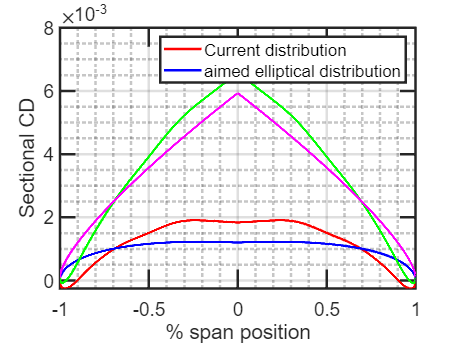


plot(1*cos(Wing.thetadist),Wing.CDi_plot,'r')
hold on
plot(-1*cos(Wing.thetadist),Wing.CDi_plot,'r')
plot(1*cos(Wing.thetadist),Wing.CDi_elliptical_plot,'b')
hold on
plot(-1*cos(Wing.thetadist),Wing.CDi_elliptical_plot,'b')



plot(1*cos(Wing.thetadist),Wing.CD_plot,'g')
hold on
plot(-1*cos(Wing.thetadist),Wing.CD_plot,'g')
plot(1*cos(Wing.thetadist),Wing.CD_elliptical_plot,'m')
hold on
plot(-1*cos(Wing.thetadist),Wing.CD_elliptical_plot,'m')

grid on
grid minor

% ylim([0 0.7])
hold off
xlabel('% span position')
ylabel('Sectional CD')
legend('Current distribution','','aimed elliptical distribution')

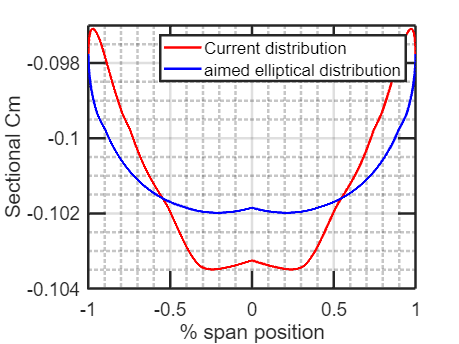



Wing.effaoa = interp1(Airfoil(2).cl,Airfoil(2).aoacl,Wing.Cl_plot);
Wing.effaoa_elliptical = interp1(Airfoil(2).cl,Airfoil(2).aoacl,Wing.Cl_ellipse_plot);
% plot (Wing.effaoa,Wing.Cl_plot,'b')
% hold on
% plot (Airfoil(2).aoacl,Airfoil(2).cl,'x')
% hold off
Wing.Cm_plot = interp1(Airfoil(1).aoacm,Airfoil(2).cm,Wing.effaoa);
Wing.Cm_elliptical_plot = interp1(Airfoil(1).aoacm,Airfoil(2).cm,Wing.effaoa_elliptical);


plot(1*cos(Wing.thetadist),Wing.Cm_plot,'r')
hold on
plot(-1*cos(Wing.thetadist),Wing.Cm_plot,'r')
plot(1*cos(Wing.thetadist),Wing.Cm_elliptical_plot,'b')
hold on
plot(-1*cos(Wing.thetadist),Wing.Cm_elliptical_plot,'b')

grid on
grid minor

% ylim([0 0.7])
hold off
xlabel('% span position')
ylabel('Sectional Cm')
legend('Current distribution','','aimed elliptical distribution')

## Iteration for liftcurve

for i = 1:10
    Wing.incidence = Wing.incidence + 0.5*pi/180;
    Wing.semispan = Wing.span*0.5;
    Wing.thetadist = acos(Wing.span_disc/Wing.span_disc(end));

    Angle.twist_dis = linspace(0,Wing.twist,length(Wing.span_disc));
    Angle.defaulttwist = Angle.twist_dis;
    Angle.twist_dis = Structure_packet.twist_plot*pi/180;

    Angle.alpha_0_dis = linspace(Airfoil(1).alpha0,Airfoil(2).alpha0,length(Wing.span_disc));
    Angle.incidence_dis = Wing.incidence*ones(1,length(Wing.span_disc));
    Angle.alpha_dis = Angle.twist_dis - Angle.alpha_0_dis + Angle.incidence_dis;

    Wing.a_dis = linspace(Airfoil(1).a,Airfoil(2).a,length(Wing.span_disc));
    Wing.mu_dis = (Wing.a_dis.*Wing.c_y)/(4.*Aircraft.AR*Wing.c_bar);




    [Wing.Lift_plot,Wing.Lift_ellipse_plot,Wing.DragI_plot,Aircraft.Totallift,Aircraft.Totalliftcheck_nofuselage,Wing.Cl_plot,Wing.Cl_ellipse_plot,Wing.CDi_plot, Wing.CL_des,Wing.CD_des_ind,Wing.Aseries,Wing.DragI_elliptical_plot,Wing.CDi_elliptical_plot] = Plotting(Angle.twist_dis, Angle.alpha_0_dis, Angle.incidence_dis, Wing.thetadist, Wing.panelnum, Wing.mu_dis,Wing.semispan,Condition.Uinf,rho.cruise,Wing.c_y,Aircraft.Sref,Condition.Cruise_Mach,Aircraft.AR,Condition.MTOW,Aircraft.fuselage_rad,Wing.span_disc);
    Wing.effaoa = interp1(Airfoil(2).cl,Airfoil(2).aoacl,Wing.Cl_plot);
    Wing.effaoa_elliptical = interp1(Airfoil(2).cl,Airfoil(2).aoacl,Wing.Cl_ellipse_plot);
    % plot (Wing.effaoa,Wing.Cl_plot,'b')
    % hold on
    % plot (Airfoil(2).aoacl,Airfoil(2).cl,'x')
    % hold off
    Wing.Cm_plot = interp1(Airfoil(1).aoacm,Airfoil(2).cm,Wing.effaoa);
    Wing.Cm_elliptical_plot = interp1(Airfoil(1).aoacm,Airfoil(2).cm,Wing.effaoa_elliptical);


    Momentcurve.Moment_plot(i) = trapz(Wing.span_disc, Wing.Cm_plot)/Wing.semispan;
    Liftcurve.Lift_plot(i) = Aircraft.Totallift;
    Liftcurve.alpha(i) = Wing.incidence*180/pi;
    Liftcurve.Cl(i) = Liftcurve.Lift_plot(i)/(0.5*rho.cruise*Condition.Uinf^2*Aircraft.Sref);
end


## Plotting liftcurve

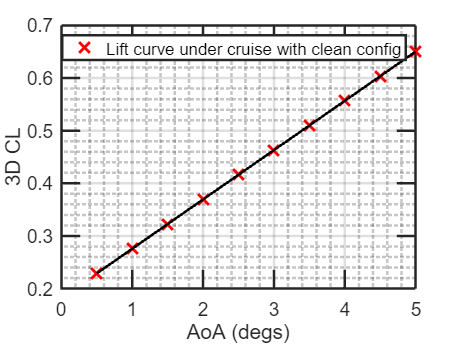


plot(Liftcurve.alpha,Liftcurve.Cl,'rx')
hold on
plot(Liftcurve.alpha,Liftcurve.Cl,'k-')
Liftcurve.Collocationvalue = polyfit(Liftcurve.alpha.*pi/180,Liftcurve.Cl,1);

Liftcurve.DATCOM = easyCLcurve(Airfoil(1).a, Condition.Cruise_Mach, 0, Aircraft.AR, Wing.S_rat, Aircraft.FLF, 0);

grid on
grid minor

% ylim([0 0.7])
hold off
xlabel('AoA (degs)')
ylabel('3D CL')
legend('Lift curve under cruise with clean config')

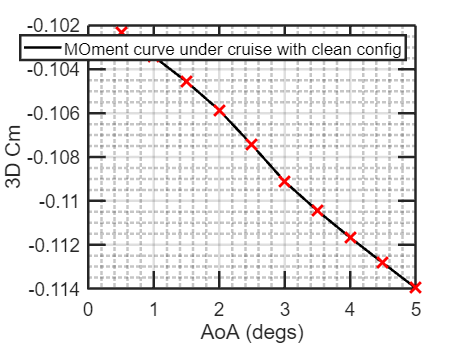

% title('Lift curve')


plot(Liftcurve.alpha,Momentcurve.Moment_plot,'k-')
hold on
plot(Liftcurve.alpha,Momentcurve.Moment_plot,'rx')
Momentcurve.Collocationvalue = polyfit(Liftcurve.alpha.*pi/180,Momentcurve.Moment_plot,1);

% Liftcurve.DATCOM = easyCLcurve(Airfoil(1).a, Condition.Cruise_Mach, 0, Aircraft.AR, Wing.S_rat, Aircraft.FLF, 0);

grid on
grid minor

% ylim([0 0.7])
hold off
xlabel('AoA (degs)')
ylabel('3D Cm')
legend('MOment curve under cruise with clean config')

% title('Lift curve')

Structure_packet_2.LiftcurveDATCOM = Liftcurve.DATCOM;
Structure_packet_2.LiftcurveCollocation = Liftcurve.Collocationvalue(1);
Structure_packet_2.aoa0ClCollocation =  Liftcurve.Collocationvalue(2);
Structure_packet_2.MomentcurveCollocation =  Momentcurve.Collocationvalue(1);
Structure_packet_2.aoa0CmCollocation =  Momentcurve.Collocationvalue(2);
Structure_packet_2.LiftcurvedistCollocation =  Liftcurve.DATCOM*ones(size(Wing.a_dis));

save('Structure_packet_2',"Structure_packet_2");

## Function for planform

function [c_y,span_disc,quarterchord,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret) 
%(AR, Sweep, Taper, c_bar) 
span = sqrt(AR * Sref);
c_bar = Sref/span;
span_disc = [0:discret:span/2];
syms croot;
eqn = (croot+Taper*croot)*(span/2) == Sref;
croot = double(solve(eqn,croot));
c_y =  (Taper-1)*croot/(span/2).*span_disc + croot;
quarterchord =  span_disc .* tand(Sweep);


% s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
% Sref_1 = (1 + Taper) * s_1;
% span_disc_1 = [0:0.01:s_1];
% c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
% c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
% ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
% s = ratio*s_1;
% Sref = ratio * (1 + Taper) * s;
% span_disc = [0:0.01:s];
% c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
% temp1 = (c_y - c_bar).^2;
% MACpos = find(temp1 == min(temp1));
% quarterchord =  span_disc .* tand(Sweep);
end

## Function for CL_3D

function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end

## Function for plotting

function [Lift_plot,Lift_ellipse_plot,DragI_plot,Totallift,Totalliftcheck,Cl_plot,Cl_ellipse_plot,CDi_plot,CL_des,CD_des_ind,Aseries,DragI_elliptical_plot,CDi_elliptical_plot] = Plotting(twist_dist, alpha_0_dis, incidence_dis, thetadist, panelnum,mu_dis,semispan,Uinf,rho,c_y,Sref,Cruise_Mach,AR,MTOW,fuselagerad,span_disc)

alpha_opt = twist_dist - alpha_0_dis + incidence_dis;

LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));
for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_opt(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end

Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;
downwash_sum = 0;
for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin((2*n-1)*thetadist);
    downwash_sum = downwash_sum + (2*n-1) * Aseries(n) * (sin((2*n-1)*thetadist)/sin(thetadist));
end

gamma_plot = gamma_span_coef*gamma_sum;
downwash_plot = Uinf*downwash_sum;
DragI_plot = rho.*downwash_plot.*gamma_plot;
downwash_elliptical_plot = Uinf*Aseries(1);

% tempa = thetadist(find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):end);
% tempb = sin(thetadist(find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):end)).^2;
% % plot(tempa,tempb)
% fuseliftloss = -2*trapz(tempa,tempb);
% A_ref = MTOW/(4*rho*Uinf^2*semispan^2*pi/2);
A_ref = Aseries(1);


gamma_ellipse = 4*semispan*Uinf*A_ref*sin(thetadist);

DragI_elliptical_plot = rho.*downwash_elliptical_plot.*gamma_ellipse;

% tempc = [1:find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad)))];
% tempd = [find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad)))];

Lift_plot = gamma_plot*Uinf*rho;
Lift_ellipse_plot = gamma_ellipse * Uinf*rho;
% Lift_plot(tempc) = 0;
% Lift_ellipse_plot(tempc) = 0;
% % Lift(tempd) = Lift(tempd) - size(2,tempd)*[1:-span_disc:0];Lift_ellipse_plot(tempd).*linspace(0,1,91)
% Lift_ellipse_plot(tempd) = 0;

Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot);
Totallift_ellipse = 2*trapz(semispan*cos(thetadist),Lift_ellipse_plot);
Totalliftcheck = 4*rho*Uinf^2*semispan^2*A_ref*pi/2;

Cl_plot = Lift_plot./(0.5*rho*Uinf^2.*c_y);
Cl_ellipse_plot = Lift_ellipse_plot./(0.5*rho*Uinf^2.*c_y);

CDi_plot = DragI_plot./(0.5*rho*Uinf^2.*c_y);
CDi_plot_check = trapz(semispan*cos(thetadist),CDi_plot)/semispan;
CDi_elliptical_plot = DragI_elliptical_plot./(0.5*rho*Uinf^2.*c_y);
CDi_ell_plot_check = trapz(semispan*cos(thetadist),CDi_elliptical_plot)/semispan;


CL_des = Totallift/(0.5*rho*Uinf^2*Sref);
CL_des_comp = pi*AR*Aseries(1);
CL_int = trapz(semispan*cos(thetadist),Cl_plot)/semispan;

CD_des_ind = (pi*AR) * sum(Aseries.*(2*[1:1:size(Aseries,1)]'-1).*Aseries);
CD_comp = (pi*AR)*Aseries(1)^2;

end




function [Lift_plot,DragI_plot,Totallift,Totalliftcheck,Cl_plot,CDi_plot,CL_des,CD_des_ind,Aseries,DragI_elliptical_plot,CDi_elliptical_plot] = propplotting(twist_dist, alpha_0_dis, incidence_dis, thetadist, panelnum,mu_dis,semispan,Uinf,rho,c_y,Sref,Cruise_Mach,AR,MTOW,fuselagerad,span_disc)

alpha_opt = twist_dist - alpha_0_dis + incidence_dis;

LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));
for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_opt(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end

Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;
downwash_sum = 0;
for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin((2*n-1)*thetadist);
    downwash_sum = downwash_sum + (2*n-1) * Aseries(n) * (sin((2*n-1)*thetadist)/sin(thetadist));
end

gamma_plot = gamma_span_coef*gamma_sum;
downwash_plot = Uinf*downwash_sum;
downwash_elliptical_plot = Uinf*Aseries(1);
DragI_plot = rho.*downwash_plot.*gamma_plot;

% tempa = thetadist(find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):end);
% tempb = sin(thetadist(find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):end)).^2;
% % plot(tempa,tempb)
% fuseliftloss = -2*trapz(tempa,tempb);
% A_ref = MTOW/(4*rho*Uinf^2*semispan^2*pi/2);
A_ref = Aseries(1);


gamma_ellipse = 4*semispan*Uinf*A_ref*sin(thetadist);

DragI_elliptical_plot = rho.*downwash_elliptical_plot.*gamma_ellipse;

% tempc = [1:find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad)))];
% tempd = [find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad))):find(abs(span_disc-fuselagerad) == min(abs(span_disc-fuselagerad)))];

Lift_plot = gamma_plot*Uinf*rho;
% Lift_ellipse_plot = gamma_ellipse * Uinf*rho;
% Lift_plot(tempc) = 0;
% Lift_ellipse_plot(tempc) = 0;
% % Lift(tempd) = Lift(tempd) - size(2,tempd)*[1:-span_disc:0];Lift_ellipse_plot(tempd).*linspace(0,1,91)
% Lift_ellipse_plot(tempd) = 0;

Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot);
Totalliftcheck = 4*rho*Uinf^2*semispan^2*A_ref*pi/2;

Cl_plot = Lift_plot./(0.5*rho*Uinf^2.*c_y);
% Cl_ellipse_plot = Lift_ellipse_plot./(0.5*rho*Uinf^2.*c_y);

CDi_plot = DragI_plot./(0.5*rho*Uinf^2.*c_y);
CDi_elliptical_plot = DragI_elliptical_plot./(0.5*rho*Uinf^2.*c_y);
CDi_plot_check = trapz(semispan*cos(thetadist),CDi_plot)/semispan;

CL_des = Totallift/(0.5*rho*Uinf^2*Sref);
CL_des_comp = pi*AR*Aseries(1);
CL_int = trapz(semispan*cos(thetadist),Cl_plot)/semispan;

CD_des_ind = (pi*AR) * sum(Aseries.*(2*[1:1:size(Aseries,1)]'-1).*Aseries);
CD_comp = (pi*AR)*Aseries(1)^2;

end